%% ===============================================================
% ACE – Water Tank Lab
% Complete Parameter Script (Modeling, a-Estimation, Pump Calibration)
% Author: Felx Raffl, Lenard Wild
% Date: 05.12.2025
% System: 4
%
% Run this script after collecting measurements from the lab.
%
% It will:
%   1) Define all physical constants
%   2) Provide tools to estimate a1 and a2 from draining experiments
%   3) Compute pump parameters K_pump and U0_pump from (h1,h2,U_in)
%   4) Build the WT parameter struct for Simulink
%   5) Save everything to WT_parameters.mat
% ================================================================

%% ------------------------------------------------------------
% 1. Physical constants
% ------------------------------------------------------------

rho = 1000;      % [kg/m^3]
g   = 9.81;      % [m/s^2]

disp("Physical constants loaded.");

Physical constants loaded.




%% ------------------------------------------------------------
% 2. Tank geometry and b-constant
% ------------------------------------------------------------

At = 50e-4;      % [m^2] = 50 cm^2
h_max = 0.30;    % [m] emergency overflow

% Mass balance constant:
%     b = 1/(rho * At)
b = 1/(rho * At);

disp("Tank geometry loaded:");

Tank geometry loaded:


At, h_max, b

At = 0.0050

h_max = 0.3000

b = 0.2000



%% ------------------------------------------------------------
% 3. a1 / a2 estimation from draining experiments
% ------------------------------------------------------------
%
% Data required:
%   t_data : time vector [s]
%   h_data : height vector [m]
%
% Import your draining measurement file first, e.g.:
%   load("03_data/lab_measurements/drain_res1.mat")
%   load("03_data/lab_measurements/drain_res2.mat")
%
% Then run this section once for reservoir 1 and once for reservoir 2.
%
% The model is:
%   h(t) = ( sqrt(h0) - (a/2)*t )^2
%
% NOTE:
%   Comment / uncomment the assignment lines at the end.


disp("Ready for a-estimation. Load drain data: t_data, h_data.");

Ready for a-estimation. Load drain data: t_data, h_data.




% --------- CHECK DATA ---------
if exist('t_data','var') && exist('h_data','var')

    t_data = t_data(:);
    h_data = h_data(:);

    % Remove negative heights
    h_data(h_data < 0) = 0;

    % Initial height
    h0 = h_data(1);

    % Model function for fitting
    model_fun = @(a,t) ( sqrt(h0) - (a/2).*t ).^2;

    % Initial guess
    a_guess = 0.1;

    % Fit using nonlinear least squares
    opts = optimoptions('lsqcurvefit','Display','off',...
        'TolFun',1e-12,'TolX',1e-12);

    [a_fit, resnorm] = lsqcurvefit(model_fun, a_guess, t_data, h_data, [], [], opts);

    fprintf("Estimated a = %.6f [m^(1/2)/s], error = %.3e\n", a_fit, resnorm);

    % Plot
    t_fine = linspace(0, t_data(end), 500);
    figure;
    plot(t_data, h_data, 'bo', 'DisplayName','Measured');
    hold on;
    plot(t_fine, model_fun(a_fit, t_fine), 'r-', 'LineWidth',2, ...
         'DisplayName','Fit');
    grid on;
    xlabel('Time [s]');
    ylabel('Height [m]');
    title(sprintf("Draining Fit (a = %.5f)", a_fit));
    legend;

    % --------- ASSIGN HERE ---------
    % If this was reservoir 1 draining:
%     a1 = a_fit;

    % If this was reservoir 2 draining:
%     a2 = a_fit;

else
    disp("Load drain_resX.mat first to estimate a.");
end

Load drain_resX.mat first to estimate a.





%% ------------------------------------------------------------
% 4. Pump calibration from h1, h2, u_in
% ------------------------------------------------------------
%
% Inputs you MUST provide:
%   meas_input_v : voltages used for calibration
%   meas_height1 : steady-state h1 for each voltage
%   meas_height2 : steady-state h2 for each voltage
%
% This section computes mass flow from:
% 
%   m_dot1 = (a1/b)*sqrt(h1)
%   m_dot2 =  rho*At*a2*sqrt(h2)
% and averages them before doing linear regression.


disp("Starting pump calibration (requires a1, a2).");

Starting pump calibration (requires a1, a2).


Mass flow estimates:


ans = 4×6 table
    U_in     h1       h2      m_dot1    m_dot2    m_dot_avg
    ____    _____    _____    ______    ______    _________

     0          0        0     NaN       NaN         NaN   
     2       0.01     0.01     NaN       NaN         NaN   
     3      0.022    0.037     NaN       NaN         NaN   
     4      0.077    0.086     NaN       NaN         NaN   


K_pump = NaN [kg/(s*V)]


U0_pump = NaN [V]


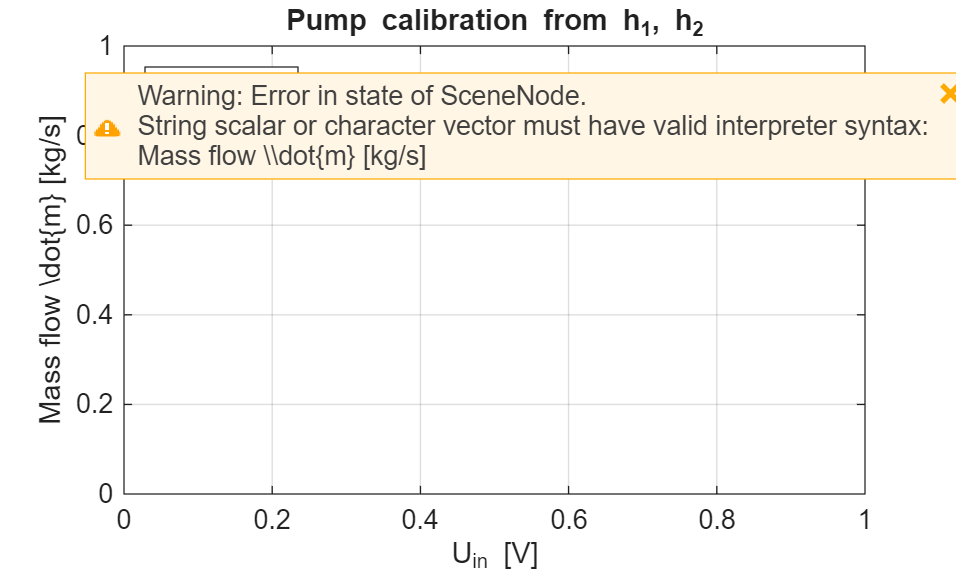



% Example placeholders (OVERWRITE with your measured data):
meas_input_v = [0 2 3 4];
meas_height1 = [0 0.01 0.022 0.077];
meas_height2 = [0 0.01 0.037 0.086];

if exist('meas_input_v','var') && exist('meas_height1','var') && exist('meas_height2','var')

    U_data = meas_input_v(:)';
    h1_ss  = meas_height1(:)';
    h2_ss  = meas_height2(:)';

    % Mass flow estimates
    m_dot1 = (a1 ./ b) .* sqrt(h1_ss);
    m_dot2 = rho * At * a2 .* sqrt(h2_ss);

    m_dot_data = 0.5 * (m_dot1 + m_dot2);

    disp("Mass flow estimates:");
    table(U_data', h1_ss', h2_ss', m_dot1', m_dot2', m_dot_data', ...
        'VariableNames', {'U_in','h1','h2','m_dot1','m_dot2','m_dot_avg'})

    % Linear fit
    p = polyfit(U_data, m_dot_data, 1);
    K_pump_lin = p(1);
    offset      = p(2);

    % Convert to m_dot = K_pump * (U - U0_pump)
    K_pump  = K_pump_lin;
    U0_pump = -offset / K_pump;

    fprintf("K_pump = %.6e [kg/(s*V)]\n", K_pump);
    fprintf("U0_pump = %.3f [V]\n", U0_pump);

    % Plot fit
    U_fit = linspace(min(U_data), max(U_data), 100);
    m_fit = polyval(p, U_fit);

    figure;
    plot(U_data, m_dot_data, 'bo','DisplayName','Data');
    hold on;
    plot(U_fit, m_fit, 'r-','LineWidth',2,'DisplayName','Fit');
    grid on;
    xlabel('U_{in} [V]');
    ylabel('Mass flow \dot{m} [kg/s]');
    title('Pump calibration from h_1, h_2');
    legend('Location','NorthWest');

else
    disp("Provide meas_input_v, meas_height1, meas_height2.");
end




%% ------------------------------------------------------------
% 5. Operating point (computed AFTER a1,a2 known)
% ------------------------------------------------------------

% Choose desired h2 steady state (e.g. 5 cm)
h2_bar = 0.05;

if exist('a1','var') && exist('a2','var') && ~isnan(a1) && ~isnan(a2)

    % h1 from steady-state equation
    h1_bar = (a2/a1)^2 * h2_bar;

    % steady inflow from tank 1 equation:
    % m_dot = (a1/b)*sqrt(h1)
    m_dot_in_bar = (a1/b)*sqrt(h1_bar);

    disp("Operating point:");
    h1_bar
    h2_bar
    m_dot_in_bar

else
    disp("Set a1 and a2 before computing operating point.");
end

Set a1 and a2 before computing operating point.





%% ------------------------------------------------------------
% 6. Assemble parameter struct WT
% ------------------------------------------------------------

WT = struct();
WT.rho  = rho;
WT.g    = g;
WT.At   = At;
WT.h_max = h_max;
WT.b    = b;

if exist('a1','var'), WT.a1 = a1; else, WT.a1 = NaN; end
if exist('a2','var'), WT.a2 = a2; else, WT.a2 = NaN; end

if exist('K_pump','var'), WT.K_pump = K_pump; else, WT.K_pump = NaN; end
if exist('U0_pump','var'), WT.U0_pump = U0_pump; else, WT.U0_pump = NaN; end

% Operating point
if exist('h1_bar','var'), WT.h1_bar = h1_bar; else, WT.h1_bar = NaN; end
WT.h2_bar = h2_bar;
if exist('m_dot_in_bar','var'), WT.m_dot_in_bar = m_dot_in_bar; else, WT.m_dot_in_bar = NaN; end

disp("WT struct created.");

WT struct created.


WT

WT = struct with fields:
             rho: 1000
               g: 9.8100
              At: 0.0050
           h_max: 0.3000
               b: 0.2000
              a1: NaN
              a2: NaN
          K_pump: NaN
         U0_pump: NaN
          h1_bar: NaN
          h2_bar: 0.0500
    m_dot_in_bar: NaN




%% ------------------------------------------------------------
% 7. Save parameters for Simulink
% ------------------------------------------------------------

save("WT_parameters.mat", "WT");
disp("Saved WT_parameters.mat successfully.");

Saved WT_parameters.mat successfully.
